==== result====
SNRin : 0.049423
SNRout: 5.4613
SNRI  : 110.5008
SNRin_dB : -13.0607
SNRout_dB: 7.373
SNRI_dB  : 20.4337


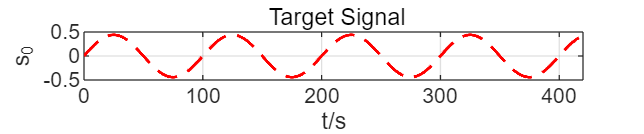

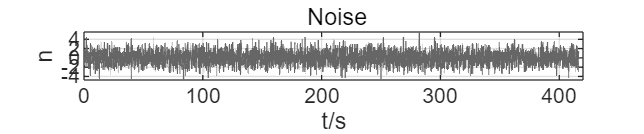

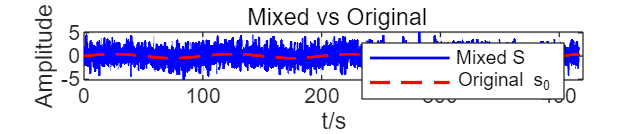

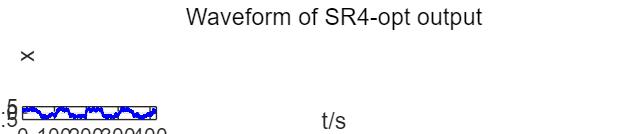

SNRI_obj = 110.5008

clc;clear;close all;
%emp
a = 18;
b = -10;
c = 5;
d = -3;
e = 3;
f = -5;
g = 80;
h = 15;

%opt white1：A=0.44、f0=0.01、σ=1.4、S0 = A*sin(2*pi*f0*t')
% a = 18.70
% b = -8.63
% c = 6.63
% d = -0.04
% e = 7.87
% f = -5.79
% g = 80.54
% h = 11.85

% %opt colored rho0.5： A=0.44、f0=0.01、σ=1.4、S0 = A*sin(2*pi*f0*t')
  % a = 20.60
  % b = -9.50
  % c = 6.72
  % d = -0.14
  % e = 2.98
  % f = -5.84
  % g = 81.86
  % h = 11.65
  
% %opt colored rho0.2： A=0.44、f0=0.01、σ=1.4、S0 = A*sin(2*pi*f0*t')
  % a = 19.23
  % b = -8.09
  % c = 4.92
  % d = -0.164826
  % e = 3.32
  % f = -6.98
  % g = 78.00
  % h = 14.83

%opt white2：A=0.5、f0=0.01、σ=1.4、S0 = A*sin(2*pi*f0*t')
% a = 20.72
% b = -8.08
% c = 6.58
% d = -0.10
% e = 6.62
% f = -7.27
% g = 81.51
% h = 11.73

%opt white3： A=0.5、f0=0.011、σ=2.0、S0 = A*cos(2*pi*f0*t')
% a = 19.99
% b = -10.00
% c = 7.25
% d = -0.38
% e = 2.00
% f = -2.83
% g = 78.12
% h = 10.85


% Input parameters [a, b, c, d, e, f, g, h]
params4D = [a, b,c,d,e,f,g,h];
% Call sr4d_eval function
%'white_gaussian','colored_gaussian'
SNRI_obj = sr4d_eval(params4D,2,'white_gaussian')


% Print output result
disp([ ' SNRI value is: ', num2str(SNRI_obj)]);

 SNRI value is: 110.5008
